directory='D:\KangDH\deVSimulation\JFT154ThermalModelBuilder'

## 1.JCR 설정 

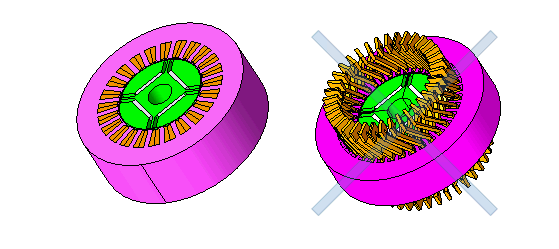

app.GetModel("rotor-Case1").GetStudy("rotor").LoadCircuit("D:/KangDH/deVSimulation/JFT154ThermalModelBuilder/base_circuit.jcir")

% Water Cooling
createJMAGThermalCircuit

% Oil Spray


## 2.JCF 설정 

6p36s

3D 모델을 on rotor Pole/Slot 기준으로 생성 

Condition(HTB, Contact) 설정 / 재질 설정 

Solid Move로 돌리기 (Geometry Editor)

Case Control로 돌리기

Export JCF File (Geometry Data for All Cases)

### Geometry

#### Rotor

app.SetCurrentStudy(1)
app.SetCurrentStudy(1)
app.GetModel(1).GetStudy(0).AddCadParameter("DMAG1@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("DMAG2@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("MT1@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("MT2@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("MW1@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("MW2@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("RS1@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("RS2@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("RS3@Variables")
app.GetModel(1).GetStudy(0).AddCadParameter("RW2@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("DMAG1@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("DMAG2@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("MT1@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("MT2@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("MW1@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("MW2@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("RS1@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("RS2@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("RS3@Variables")
app.GetModel(1).GetStudy(0).GetDesignTable().AddCadParameterVariableName("RW2@Variables")

### Solid Move로 돌리기 (Geometry Editor)

setting 하는 variable 값은 int32로 넣어야됨

app = actxserver(strcat('Designer.Application.','222'));
CurrentModel=app.GetCurrentModel()
CurrentModel.GetName()
CurrentModel.RestoreCadLink(1)
geomApp                           = app.CreateGeometryEditor(0)
geomApp.
geomApp.GetDocument().GetAssembly().GetItem('Rotor.2').OpenPart();
geomApp.GetDocument().GetAssembly().GetItem('Rotor.2').CreateSolidMove();
a=geomApp.GetDocument().GetAssembly().GetItem('Rotor.2')

geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").OpenPart()
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").CreateSolidMove()
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").GetItem("Solid Move.13").SetProperty("Name", "Solid Move.2")
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").GetItem("Solid Move.2").SetProperty("MoveType", int32(1))
refarray = cell(1, 1);
refarray{1} = 'lump(TImportFeature32)';
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").GetItem("Solid Move.2").SetProperty("SolidList", refarray{1})
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").GetItem("Solid Move.2").SetProperty("Angel", "move_angle")
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").GetItem("Solid Move.2").SetProperty("AxisType", int32(4))
geomApp.GetDocument().GetAssembly().GetItem("Rotor.2").ClosePart()


CurrentModel.RestoreCadLink(1)
geomApp.InsertGeometryLibrary("Motor\Rotor\2D Geometries\Permanent Magnet(IPM-Inner)\Inverted triangle")

app.GetModel(1).GetStudy(0).SetCadParameterValue("RD1@Variables", 154.2)

app.GetModel(1).GetStudy(0).SetCadParameterValue("DMAG1@Variables", 140/2)
app.GetModel(1).GetStudy(0).SetCadParameterValue("DMAG2@Variables", 100/2)
app.GetModel(1).GetStudy(0).SetCadParameterValue("RD1@Variables", 154.2)
app.GetModel(1).GetStudy(0).SetCadParameterValue("RD1@Variables", 154.2)
app.GetModel(1).GetStudy(0).SetCadParameterValue("RD1@Variables", 154.2)



### Condition - Registor variables

tempThermalInputVariable
%% Stator
% Contact Resistance Coil-Core
% HTB
    % Stator Core Surface

    % Coil

    % St-RT Gap

%% Rotor
% Contact Thermal Resistance : Magnet
% HTB
    % Rotor Surface
    % Rotor Gap

 

### `#rotor`

#### Initial Setting

#### Python Setting


% 우선 JCF로부터 Condition 가져오는듯 
app.GetModel(1).GetStudy(0).MergeJcf(directory.decode() + "/rotor/rotor-Case"+str(i+2)+".jcf")
% name change
app.SetCurrentStudy(1)

app.GetModel(1).GetStudy(0).GetCondition("HTB_rotor_surface1").GetName()


### `#stator`

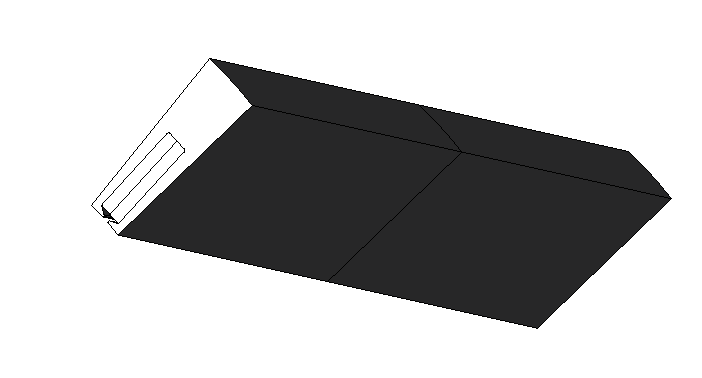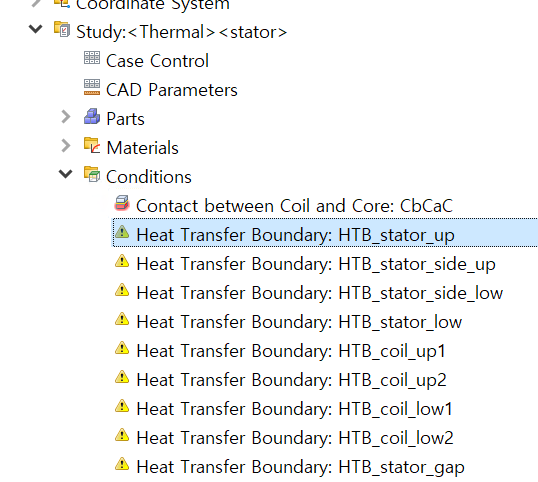

#### Initial Setting

% app.GetModel("stator-Case1").GetStudy("stator_Test").DeleteCondition("HTB_stator_side_up")

%% 
app.GetModel("stator-Case1").GetStudy("stator_Test").CreateCondition("HeatTransfer", "untitled 1")
app.GetModel("stator-Case1").GetStudy("stator_Test").GetCondition("untitled 1").SetValue("RefTemperatureType", int32(1))
app.GetModel("stator-Case1").GetStudy("stator_Test").GetCondition("untitled 1").SetValue("Coefficient", "HTC")
app.GetModel("stator-Case1").GetStudy("stator_Test").GetCondition("untitled 1").SetCoordinateSystem("FileName_CoordinateId", "Global Rectangular")
app.GetModel("stator-Case1").GetStudy("stator_Test").GetCondition("untitled 1").ClearParts()

%% Selection & add Face in Condition
sel = app.GetModel("stator-Case1").GetStudy("stator_Test").GetCondition("untitled 1").GetSelection()
sel.SelectFace(33)
app.GetModel("stator-Case1").GetStudy("stator_Test").GetCondition("untitled 1").AddSelected(sel)


#### Python Setting

app.GetModel(1).GetStudy(0).MergeJcf(directory.decode() + "/stator/stator-Case"+str(i+1)+".jcf")

% Merge했으니까 ModelIndex 2 임 
app.GetModel(2).GetStudy(0).GetCondition("HTB_stator_up").SetName("HTB_stator_up"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_stator_side_up").SetName("HTB_stator_side_up"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_stator_side_low").SetName("HTB_stator_side_low"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_stator_low").SetName("HTB_stator_low"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_coil_up1").SetName("HTB_coil_up1"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_coil_low1").SetName("HTB_coil_low1"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_coil_up2").SetName("HTB_coil_up2"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_coil_low2").SetName("HTB_coil_low2"+str(i+1))
app.GetModel(2).GetStudy(0).GetCondition("HTB_stator_gap").SetName("HTB_stator_gap"+str(i+1))

app.DeleteModel(1)


### `#Grouping`

`why? 원래 JCF가 그룹이 되어있어서 그룹을 모두 제거하고 다시 이름으로 Group 설정`

`part이름별로 그룹 설정후 Condition - mesh condition인듯 `

app.GetModel(1).GetGroupList().RemoveAllGroups()
app.GetModel(1).GetGroupList().CreateGroupByName()
app.GetModel(1).GetStudy(0).GetMeshControl().CreateCondition("Part", "untitled 1")
app.GetModel(1).GetStudy(0).GetMeshControl().GetCondition(0).SetValue("Size", 100)
app.GetModel(1).GetStudy(0).GetMeshControl().GetCondition(0).ClearParts()
sel = app.GetModel(1).GetStudy(0).GetMeshControl().GetCondition(0).GetSelection()
sel.SelectPart("Coil")
sel.SelectPart("Magnet")
sel.SelectPart("Stator")
sel.SelectPart("Rotor")
app.GetModel(1).GetStudy(0).GetMeshControl().GetCondition(0).AddSelected(sel)

## `여기서 `

### `#Add Measurement Varables`

`Jcf별로 Moveangle이 있음`

app.GetModel(1).GetStudy(0).GetDesignTable().RemoveEquation("move_angle")
app.GetModel(1).GetStudy(0).GetDesignTable().AddMeasurementVariable("stator_side_area")
app.GetModel(1).GetStudy(0).GetDesignTable().GetMeasurementVariable("stator_side_area").SetType("Face")
app.GetModel(1).GetStudy(0).GetDesignTable().AddMeasurementVariable("core_stator_area")
app.GetModel(1).GetStudy(0).GetDesignTable().GetMeasurementVariable("core_stator_area").SetType("Face")
app.GetModel(1).GetStudy(0).GetDesignTable().AddMeasurementVariable("core_rotor_area")
app.GetModel(1).GetStudy(0).GetDesignTable().GetMeasurementVariable("core_rotor_area").SetType("Face")
app.GetModel(1).GetStudy(0).GetDesignTable().AddMeasurementVariable("gap_area")
app.GetModel(1).GetStudy(0).GetDesignTable().GetMeasurementVariable("gap_area").SetType("Face")
app.GetModel(1).GetStudy(0).GetDesignTable().AddMeasurementVariable("coilend_area")
app.GetModel(1).GetStudy(0).GetDesignTable().GetMeasurementVariable("coilend_area").SetType("Face")

app.GetModel(1).GetStudy(0).GetDesignTable().AddMeasurementVariable("coilend_area1")
app.GetModel(1).GetStudy(0).GetDesignTable().GetMeasurementVariable("coilend_area1").SetType("Face")


### `#[key Point] Calculate valiables`

% Calculate variables
calcThermalSubVariable

### `#Load Circuit`

% Load Circuit
rotorModel = app.GetModel(1);
rotorStudy = rotorModel.GetStudy(0);
rotorStudy.LoadCircuit([directory '/base_circuit.jcir']);

for i = 1:poles
    componentNames = {'rotor_gap', 'rotor_surface', 'rotor_low', 'rotor_shaft'};
    instanceNames = {[componentNames{1} num2str(i)], [componentNames{2} num2str(i)], ...
        [componentNames{3} num2str(i)], [componentNames{4} num2str(i)]};
    
    rotorCircuit = rotorStudy.GetCircuit();
    
    for j = 1:numel(componentNames)
        rotorCircuit.CreateComponent('HeatTransferBoundary', componentNames{j});
        rotorCircuit.CreateInstance(instanceNames{j}, -98 + 4*(i-1), 41);
        rotorCircuit.CreateWire(-102 + 4*(i-1), 42, -98 + 4*(i-1), 42);
        rotorStudy.GetCondition(['HTB_' componentNames{j} num2str(i)]).SetLink(instanceNames{j});
    end
end

for i = 1:slots
    componentNames = {'stator_gap', 'stator_up', 'stator_side_up', 'stator_side_low', 'stator_low'};
    instanceNames = {[componentNames{1} num2str(i)], [componentNames{2} num2str(i)], ...
        [componentNames{3} num2str(i)], [componentNames{4} num2str(i)], [componentNames{5} num2str(i)]};
    
    rotorCircuit = rotorStudy.GetCircuit();
    
    for j = 1:numel(componentNames)
        rotorCircuit.CreateComponent('HeatTransferBoundary', componentNames{j});
        rotorCircuit.CreateInstance(instanceNames{j}, -98 + 4*(i-1), 45);
        rotorCircuit.CreateWire(-102 + 4*(i-1), 46, -98 + 4*(i-1), 46);
        rotorStudy.GetCondition(['HTB_' componentNames{j} num2str(i)]).SetLink(instanceNames{j});
    end
end




### `# set valiables`

for i = 1:slots
    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("ThermalResistor", strcat("R_coil_up1_to_air", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("R_coil_up1_to_air", num2str(i)), -98+8*i, -12);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up1_to_air", num2str(i)), 0).RotateTo(90);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up1_to_air", num2str(i)), 0).MoveTo(-100+8*i, -14);
    app.GetModel(1).GetStudy(0).GetCircuit().GetComponent(strcat("R_coil_up1_to_air", num2str(i))).SetValue("ThermalResistor", strcat("(1/HTC_air)/(coilend_area/1000000)"));

    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("HeatCapacity", strcat("C_coil_up1", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("C_coil_up1", num2str(i)), -103+8*i, -16);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("C_coil_up1", num2str(i)), 0).MoveTo(-102+8*i, -16);
    app.GetModel(1).GetStudy(0).GetCircuit().GetComponent(strcat("C_coil_up1", num2str(i))).SetValue("HeatCapacity", strcat("coilend_specific_heat*coilend_density*coilend_height*coilend_area/1000000000"));
    
    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("ThermalResistor", strcat("R_coil_up1", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("R_coil_up1", num2str(i)), -98+8*i, -16);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up1", num2str(i)), 0).RotateTo(90);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up1", num2str(i)), 0).MoveTo(-100+8*i, -18);
    app.GetModel(1).GetStudy(0).GetCircuit().GetComponent(strcat("R_coil_up1", num2str(i))).SetValue("ThermalResistor", strcat("(1/coilend_conductivity)/(coilend_area/1000000)*(coilend_height/1000)"));

    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("HeatTransferBoundary", strcat("coil_up1", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("coil_up1", num2str(i)), -100+8*i, -21);

    app.GetModel(1).GetStudy(0).GetCircuit().CreateWire(-100+8*i, -12, -96+8*i, -12);

    app.GetModel(1).GetStudy(0).GetCondition(strcat("HTB_coil_up1", num2str(i))).SetLink(strcat("coil_up1", num2str(i)));

    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("ThermalResistor", strcat("R_coil_up2_to_air", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("R_coil_up2_to_air", num2str(i)), -98+4+8*i, -12);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up2_to_air", num2str(i)), 0).RotateTo(90);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up2_to_air", num2str(i)), 0).MoveTo(-100+4+8*i, -14);
    app.GetModel(1).GetStudy(0).GetCircuit().GetComponent(strcat("R_coil_up2_to_air", num2str(i))).SetValue("ThermalResistor", strcat("(1/HTC_air)/(coilend_area/1000000)"));

    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("HeatCapacity", strcat("C_coil_up2", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("C_coil_up2", num2str(i)), -103+4+8*i, -16);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("C_coil_up2", num2str(i)), 0).MoveTo(-102+4+8*i, -16);
    app.GetModel(1).GetStudy(0).GetCircuit().GetComponent(strcat("C_coil_up2", num2str(i))).SetValue("HeatCapacity", strcat("coilend_specific_heat*coilend_density*coilend_height*coilend_area/1000000000"));

    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("ThermalResistor", strcat("R_coil_up2", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("R_coil_up2", num2str(i)), -98+4+8*i, -16);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up2", num2str(i)), 0).RotateTo(90);
    app.GetModel(1).GetStudy(0).GetCircuit().GetInstance(strcat("R_coil_up2", num2str(i)), 0).MoveTo(-100+4+8*i, -18);
    app.GetModel(1).GetStudy(0).GetCircuit().GetComponent(strcat("R_coil_up2", num2str(i))).SetValue("ThermalResistor", strcat("(1/coilend_conductivity)/(coilend_area/1000000)*(coilend_height/1000)"));

    app.GetModel(1).GetStudy(0).GetCircuit().CreateComponent("HeatTransferBoundary", strcat("coil_up2", num2str(i)));
    app.GetModel(1).GetStudy(0).GetCircuit().CreateInstance(strcat("coil_up2", num2str(i)), -100+4+8*i, -21);

    app.GetModel(1).GetStudy(0).GetCircuit().CreateWire(-100+4+8*i, -12, -96+4+8*i, -12);

    app.GetModel(1).GetStudy(0).GetCondition(strcat("HTB_coil_up2", num2str(i))).SetLink(strcat("coil_up2", num2str(i)));

    % Repeat similar code blocks for coil_low1 and coil_low2 instances/components here
end


### `# contact`

###     `#Add Condition`


DMAG1
DMAG2
MODEL_DIVISION
MT1
MT2
MW1
MW2
NUM_CIRCULAR_PATTERNS
POLES
RD1
RD2
RS
RS1
RS2
RS3
RW2
SLOTS
WMAG2